**Ercihan Kara - 2375160**

## Data Acquisition and Data Generation

+ Sound data from a microphone:

    - Capture the voice by the help of a microphone   connected to the computer.

    - Analog-to-digital conversion sampling rate is adjustable on a user interface.

    - The total length of the generated data is also a user-specified parameter (guessing lifetime of mic input).

+ Sound data from a file:

    - Be able to process .wav or .mp3 sound files.

    - Retrieve the time-domain signal and the sampling frequency.

    - Use single channel.

+ If the input signal is a speech signal, the required process in order to record and save it is realized above.

+ System must be able to generate the samples of time-domain signals with some simple mathematical expressions.

+ The sampling frequency is a user-specified parameter. The total length of the generated data is also a user-specified parameter. It can be input in seconds or in number of samples.

samp_rate = 8000

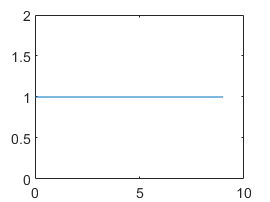

clear all
clc
% USER INTERFACES
% initial interface to decide on whether the mic is used or a file is utilized:

type = "none";

user_int_decide = {'Input type (mic or file or custom):'};
title = 'Choose input type';
dims = [1 40];
type_input = inputdlg(user_int_decide, title, dims);

if type_input == "mic"
    type = "mic";
elseif type_input == "file"
    type = "file";
else
    type = "custom";
end

if type == "mic"
    % user interface to get the sampling rate

    user_int_mic = {'A-to-D sampling rate (Hz):','Length of the generated data (sec):'};
    title = 'Type the sampling rate and length of voice';
    dims = [1 40];
    defalut_input = {'8000', '5'};
    mic_inputs = inputdlg(user_int_mic, title, dims, defalut_input);

elseif type == "file"
    % user interface to get the file address

    user_int_file = {'File address:'};
    title = 'Type the address of the file';
    dims = [1 40];
    file_input = inputdlg(user_int_file, title, dims);

else
    % user interface to get sampling rate and length for the custom signal

    user_int_custom = {'Sampling rate (Hz):','Length of the generated data (# of samples):'};
    title = 'Type the sampling rate and length of custom signal';
    dims = [1 40];
    custom_inputs = inputdlg(user_int_custom, title, dims);
end

% First consider the mic case:
% Create an audiorecorder object with the specified sampling rate using one channel:
if type == "mic"
    % audiorecorder creates and returns an audiorecorder object with specified properties

    samp_rate_mic = str2double(mic_inputs(1)); % 8000 default
    bits = 8; % default
    channels = 1; % default
    ID = -1; % default
    
    % object created
    obj = audiorecorder(samp_rate_mic, bits, channels, ID);
    
    % record the input voice
    disp("SPEAK")
    duration = str2double(mic_inputs(2)); % users' desired time period
    recordblocking(obj, duration);
    disp("FINITO")
    
    % save the voice data
    voice_mic = getaudiodata(obj, 'double');

    % play it to check
    play(obj);

% Then consider the file case:
elseif type == "file"
    % audioread reads data from the file, returns sampled data and sample
    % rate for the data

    [voice_file, samp_rate_file] = audioread(file_input);

% And consider the custom case:
else
    % create a sinusoidal signal for the "implementation" section as the
    % custom signal
    samp_rate = str2double(custom_inputs(1));
    length = str2double(custom_inputs(2));
    t_custom = 0:length-1;

    % sinusoidal signal: 𝑥(𝑡)=𝐴cos(2𝜋𝑓𝑡+𝜃)
    magn = 1; % default assigned ???
    phase = 0; % default assigned ???
    signal = magn*cos(2*pi*samp_rate*t_custom + phase);
    plot(t_custom, abs(signal))
end

**Take the window signal type and create the STFT of the input signal:**

user_int_window = {'Window type (tukey, blackman, hamming, hanning, kaiser, gaussian, triangular, or press enter for rectangular):'};
title = 'Choose window type';
dims = [1 80];
defalut_input = {''};
win_type_input = inputdlg(user_int_window, title, dims);

% create the STFT